%% Q4 - Tests

% PARAMETERS
m = 50;          % max iterations
tol = 1e-8;      % tolerance

% Small-scale SuiteSparse matrix
fprintf('\n----SMALL SCALE----\n')


----SMALL SCALE----


n = 500;
A = sprand(n,n,0.01);   % 1% density sparse matrix
b = randn(n,1);
x0 = zeros(n,1);

fprintf('Matrix size: %d x %d\n', n, n)

Matrix size: 500 x 500


fprintf('Nonzeros: %d\n\n', nnz(A))

Nonzeros: 2493




% Basic GMRES
tic
[x1,res1] = gmres_basic(A,b,x0,m,tol);
t1 = toc;

% Givens GMRES
tic
[x2,res2] = gmres_givens(A,b,x0,m,tol);
t2 = toc;

% Monitor GMRES
tic
[x3,res3] = gmres_monitor(A,b,x0,m,tol);
t3 = toc;

fprintf('Basic GMRES:   %.4f s\n',t1)

Basic GMRES:   0.0041 s


fprintf('Givens GMRES:  %.4f s\n',t2)

Givens GMRES:  0.0024 s


fprintf('Monitor GMRES: %.4f s\n',t3)

Monitor GMRES: 0.0023 s


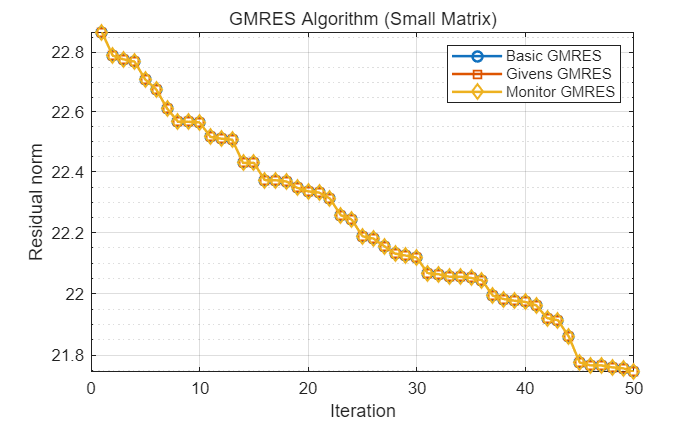


% Plotting
figure
semilogy(res1,'-o','LineWidth',1.5)
hold on
semilogy(res2,'-s','LineWidth',1.5)
semilogy(res3,'-d','LineWidth',1.5)

legend('Basic GMRES','Givens GMRES','Monitor GMRES')
xlabel('Iteration')
ylabel('Residual norm')
title('GMRES Algorithm (Small Matrix)')
grid on




% Large-scale SuiteSparse matrix
fprintf('\n----LARGE SCALE----\n')


----LARGE SCALE----


n = 20000;
A = sprand(n,n,0.0005);  % very sparse
b = randn(n,1);
x0 = zeros(n,1);

fprintf('Matrix size: %d x %d\n', n, n)

Matrix size: 20000 x 20000


fprintf('Nonzeros: %d\n', nnz(A))

Nonzeros: 199954



% Basic GMRES
tic
[x1,res1] = gmres_basic(A,b,x0,m,tol);
t1 = toc;

% Givens GMRES
tic
[x2,res2] = gmres_givens(A,b,x0,m,tol);
t2 = toc;

% Monitor GMRES
tic
[x3,res3] = gmres_monitor(A,b,x0,m,tol);
t3 = toc;

fprintf('Basic GMRES:   %.4f s\n',t1)

Basic GMRES:   0.1599 s


fprintf('Givens GMRES:  %.4f s\n',t2)

Givens GMRES:  0.0668 s


fprintf('Monitor GMRES: %.4f s\n',t3)

Monitor GMRES: 0.0624 s


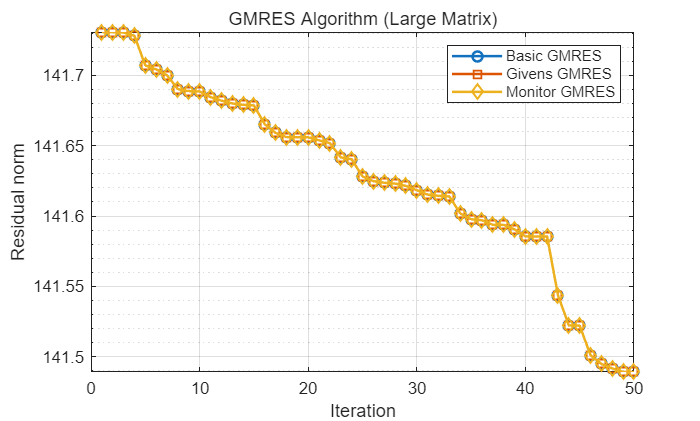


% Plotting
figure
semilogy(res1,'-o','LineWidth',1.5)
hold on
semilogy(res2,'-s','LineWidth',1.5)
semilogy(res3,'-d','LineWidth',1.5)

legend('Basic GMRES','Givens GMRES','Monitor GMRES')
xlabel('Iteration')
ylabel('Residual norm')
title('GMRES Algorithm (Large Matrix)')
grid on